# Matlab CheatSheet

## I/O

끝에 ;를 붙히면 결과를 창에 보여주지 X

i = 3;
disp(3);

     3



A =      1     2     3
     4     5     6
     7     8     9


## 함수 사용법 찾기

help zeros

zeros - 모두 0으로 구성된 배열 생성

     스칼라 0을 반환합니다.

    X = zeros
    X = zeros(n)
    X = zeros(sz1,...,szN)
    X = zeros(sz)
    X = zeros(___,typename)
    X = zeros(___,'like',p)

    참고 항목 <a href="https://www.mathworks.com/help/releases/R2017b/matlab/ref/complex.html">complex</a>, <a href="https://www.mathworks.com/help/releases/R2017b/matlab/ref/eye.html">eye</a>, <a href="https://www.mathworks.com/help/releases/R2017b/matlab/ref/false.html">false</a>, <a href="https://www.mathworks.com/help/releases/R2017b/matlab/ref/ones.html">ones</a>, <a href="https://www.mathworks.com/help/releases/R2017b/matlab/ref/rand.html">rand</a>, <a href="https://www.mathworks.com/help/releases/R2017b/matlab/ref/size.html">size</a>

    zeros에 대한 함수 도움말 문서 페이지



# Symbolic Toolbox

## Symbolic 생성

syms x;
syms x positive;
syms x y real;

## Symbolic 함수 정의

syms f(x);
f(x) = x^2 + 3*x;

syms g(x,y);
g(x,y) = x^2*y;

## Symbolic 계산

disp(f(1)); % 1을 대입한 결과

$$4$$

## Graph 그리기

fplot(f(x));

fmesh(g(x,y)); % 2변수 함수 그리기

## Graph 꾸미기

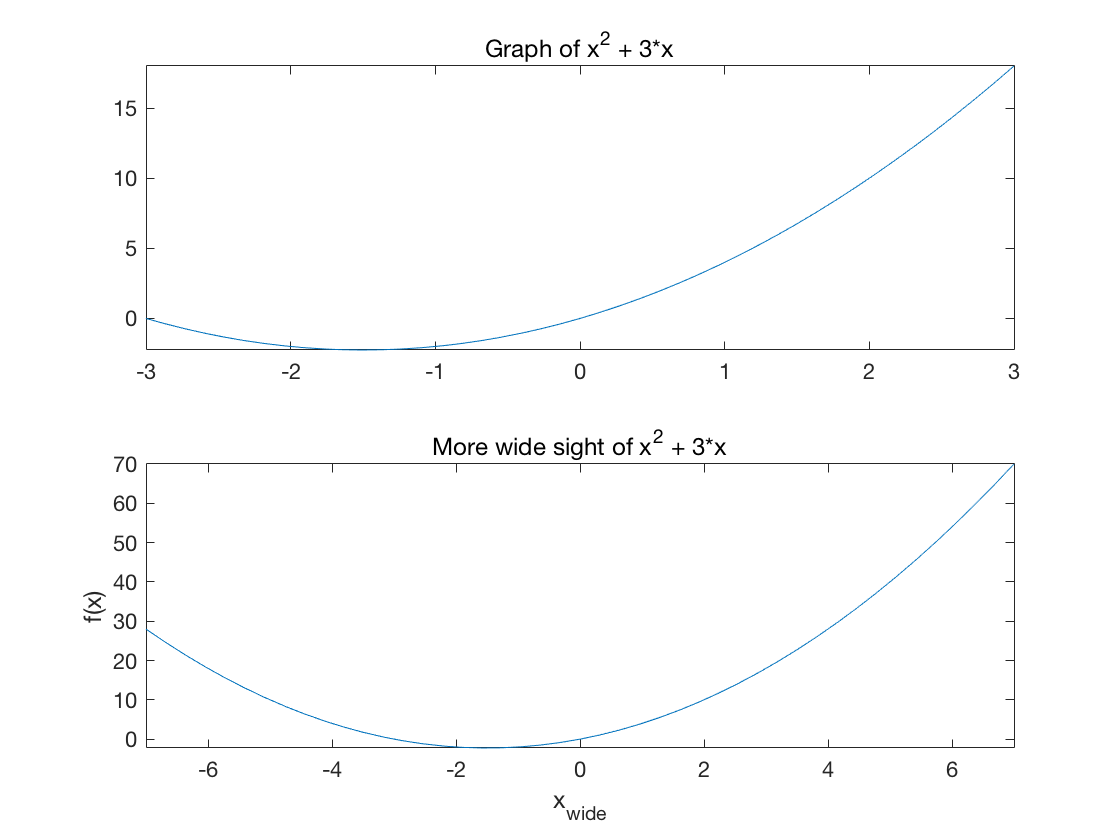

subplot(211);               % 그래프의 칸을 나누어 위쪽에 그리기
fplot(f(x));
axis([-3 3 -inf inf]);      % 보고 싶은 범위 지정
title('Graph of x^2 + 3*x');% 제목 지정

subplot(212);               % 그래프의 칸을 나누어 아래쪽에 그리기
fplot(f(x));
axis([-7 7 -inf inf]);
title('More wide sight of x^2 + 3*x');

xlabel('x_{wide}');
ylabel('f(x)');

## Solve(  )

방정식 정의

eqn = (x-3)*(2*x-4)==0

$$eqn = \left(2\,x-4\right)\,\left(x-3\right)=0$$

연립방정식 풀기

syms u v
eqns = [2*u + v == 0, u - v == 1];
S = solve(eqns, [u v])

S = 다음 필드를 포함한 struct :
    u: [1×1 sym]
    v: [1×1 sym]


미분방정식 풀기

syms y(t) a
eqn = diff(y,t) == a*y;
cond = y(0) == 5;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = 5\,{\mathrm{e}}^{a\,t}$$

## 유용한 Symbolic 함수

eqn2 = x^2 + 2 + 3*x

$$eqn2 = x^{2}+3\,x+2$$

식 펼치기

expand(eqn2)

$$ans = x^{2}+3\,x+2$$

식 묶기

factor(eqn2)

$$ans = \left(\begin{array}{cc} x+2 & x+1 \end{array}\right)$$

식 정리

collect(eqn2,x)

$$ans = x^{2}+3\,x+2$$

Sym결과를 숫자로

generalU = double(S.u)

generalU = 0.3333